b = 1.02;
c = 0.08;
h = 0.8603;
lambda = pi/10;
V = 5.7; % m/s
a = 0.347;
g = 9.81;
m = 84;

k1 = b^2/((V^2*sin(lambda) - b*g*cos(lambda))*m*a*c*sin(lambda));
k2 = b*g/(V^2*sin(lambda) - b*g*cos(lambda));

% k1 = 5;
% k2 = 1;

sys_tf = get_bicycle_fb_tf(h, V, a,b,k1,k2,c,lambda);
sys_tf

sys_tf =
 
     1.921 s + 31.25
  ---------------------
  s^2 + 13.31 s + 205.2
 
Continuous-time transfer function.



% bode(sys_tf);

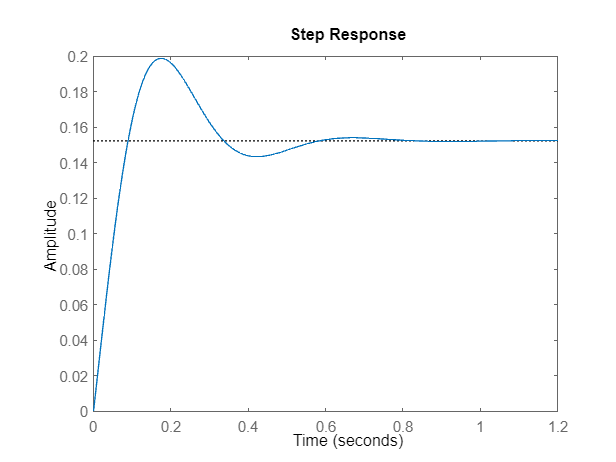

step(sys_tf);

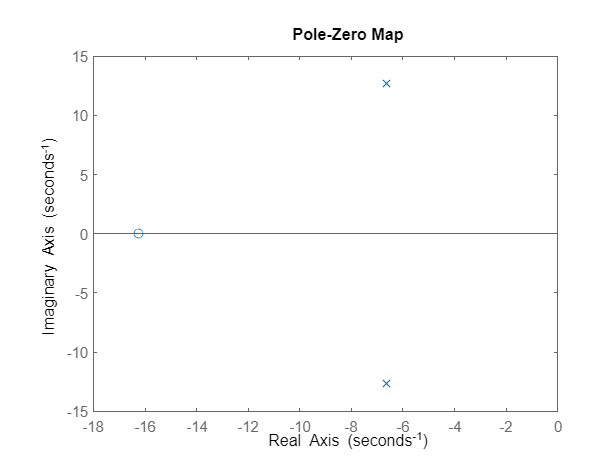

pzmap(sys_tf);

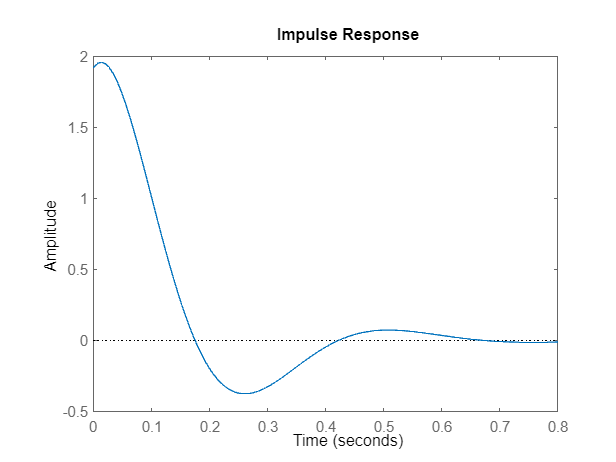

impulse(sys_tf);

% rlocus(sys_tf);

% nyquist(sys_tf);

% nichols(sys_tf);

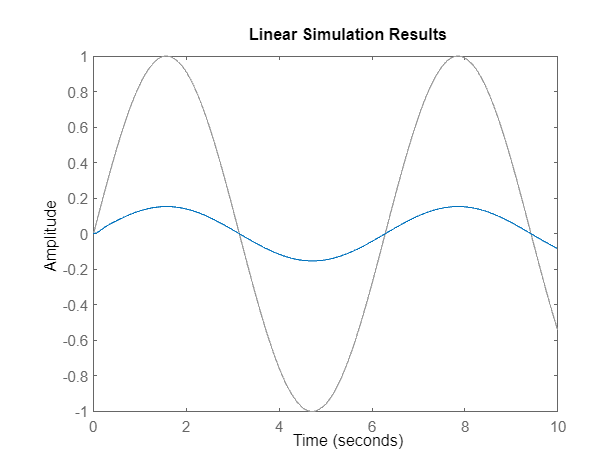

t = 0:0.01:10; % Time vector
u = sin(t); % Example input
lsim(sys_tf, u, t);

**State space analysis**

%A = [
    %0                       1;
    %g/h-k2*V^2/(b*h)    -a*V/(b*h)
%];

%B = [
                %a*V/(b*h)*k1;
    %-(a*V/(b*h))^2*k1 + V^2/(b*h)*k1;
%];

%C = [1 0];
%D = 0;

% ccf
A = [
    0                                                       1;
    g/h - k2*(V^2*h-a*c*g)*sin(lambda)/(b*h^2)    -a*V*sin(lambda)/(b*h)*k2
];
B = [
    0;
    1
];

C = [(V^2*h-a*c*g)*sin(lambda)/(b*h^2)*k1 a*V*sin(lambda)/(b*h)*k1];
D = 0;


sys_ss = ss(A,B,C,D)

sys_ss =
 
  A = 
           x1      x2
   x1       0       1
   x2  -205.2  -13.31
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
          x1     x2
   y1  31.25  1.921
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



eig(A)

ans =   -6.6567 +12.6826i
  -6.6567 -12.6826i


pole(sys_tf)

ans =   -6.6567 +12.6826i
  -6.6567 -12.6826i


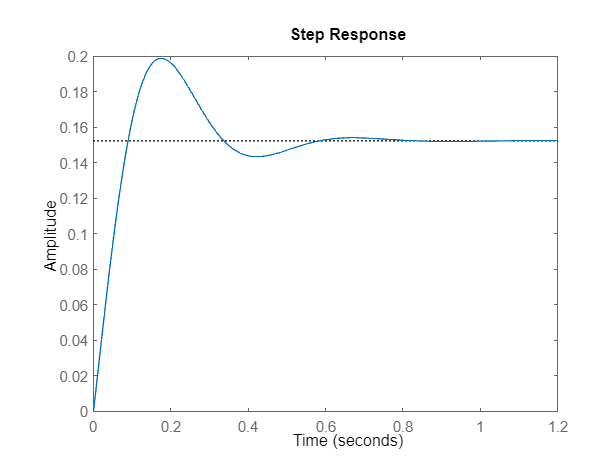

step(sys_ss)

**Stability Analysis**

Q = eye(length(A));
P = lyap(A,Q);

if all(eig(P) > 0)
    disp('The system is stable.')
else
    disp('The system is not stable.')
end

The system is stable.


**Controllability and Observability Analysis**

obsy = obsv(sys_ss);
conty = ctrb(sys_ss);

if rank(conty) == length(A)
    disp('The system is controllable.')
else
    disp('The system is not controllable.')
end

The system is controllable.


if rank(obsy) == length(A)
    disp('The system is observable.')
else
    disp('The system is not observable.')
end

The system is observable.


if rank(obsy) == length(A) && rank(conty) == length(A)
    disp('This realization is minimal.')
else
    disp('This realization is not minimal.')
end

This realization is minimal.


**Luenberge Observer**

observer_poles = [-12, -12];
L_t = acker(A', C', observer_poles );
L = L_t'

L =     0.4831
   -2.2958


A_obs = A-L*C

A_obs =   -15.0970    0.0719
 -133.4168   -8.9030


B_obs = [B L] % input is [u Y]'

B_obs =          0    0.4831
    1.0000   -2.2958


C_obs = eye(length(A_obs)) % since we want all the states

C_obs =      1     0
     0     1


D_obs = zeros(size(B_obs))

D_obs =      0     0
     0     0
